clear all
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t)

m1=4; m2=2;L=3; 

IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];
g=9.81;

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]);
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;


%As usual, set up equations of motion.  NOTICE THE CONSTITUATIVE RELATION
%F2==-F3 goes in the DEs!  This is because that equation doesn't need to be
%differentiated.  Maybe we should do something about that for clarity?

DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];


%Treat the problem numerically, as a DAE.  Give a hint on the inital
%condition. Plot the resulting configuration.  Looks strange. See if you
%are at least conserving energy. 
soln=mechanicsAsDAE(DES,PositionConstraints,[],[0,20],...
    {x1(t)==0.5,theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},{y1==sqrt(2)},0);

The unknown functions (just the base functions, not derivatives) are: F1x(t),F2x(t),F3x(t),F1y(t),F2y(t),F3y(t),theta1(t),theta2(t),x1(t),x2(t),y1(t),y2(t)
Multiple feasible initial conditions found:
Dx1t: -1.414214    Dx2t: -2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 2.801756    x2: 2.060660    y1: 1.414214    y2: 1.767767    
Dx1t: 1.414214    Dx2t: 2.828427    Dy1t: 0.500000    Dy2t: 1.000000    theta1: 0.339837    x2: 2.060660    y1: -1.414214    y2: -3.889087    

Selecting IC:
Dx1t:-1.414214    Dx2t:-2.828427    Dy1t:0.500000    Dy2t:1.000000    theta1:2.801756    x2:2.060660    y1:1.414214    y2:1.767767    
Because it is closest to satisfying the hints.

Initial Conditions:
Y0/YP0:
F1x: 8.670894 F1xt:0.000000
F2x: -0.909148 F2xt:0.000000
F3x: 0.909148 F3xt:0.000000
F1y: 33.791097 F1yt:0.000000
F2y: -3.659250 F2yt:0.000000
F3y: 3.659250 F3yt:0.000000
theta1: 2.801756 theta1t:1.000000
theta2: 0.785398 theta2t:0.000000
x1: 0.500000 x1t:-1.414214
x2: 2.060660 x2t:-2.82

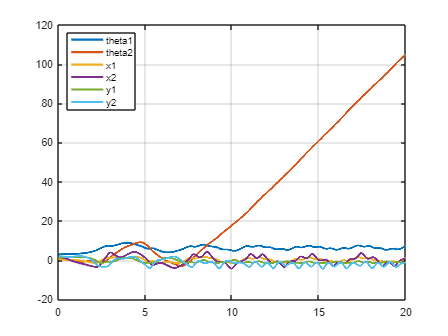

plot(soln.t,soln.theta1,soln.t,soln.theta2,soln.t,soln.x1,soln.t,soln.x2,soln.t,soln.y1,soln.t,soln.y2,'LineWidth',2); grid on; legend({"theta1","theta2","x1","x2","y1","y2"},'location','best');

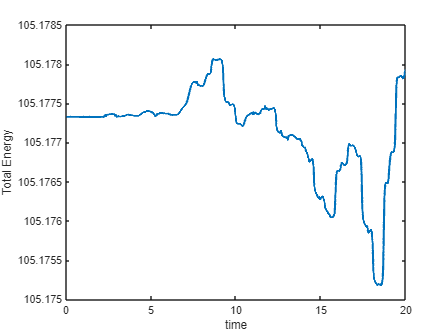

%See if we are conserving energy. 
KineticEnergy=1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)...
    +1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2;
PotentialEnergy=m1*soln.y1*g+m2*soln.y2*g;
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')

%Get a general set of governing equations. 
clear m1 m2 L g
syms m1 m2 L g
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3);

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]);
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3);

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;

DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];

[governingEqs,PPs]=analyzeSystem(DES,PositionConstraints,[],[theta1,diff(theta1),theta2,diff(theta2)]);
governingEqs

%Plug in the same m1, m2, L, g from above, use the timestepper to see if we
%match results with the DAE solver.  

%THEY DON'T MATCH!!  But, if you look on a shorter time window, like [0,5],
%they look good. This isn't too unexpected for a chaotic system. 

specificGoverningEqns=subs(governingEqs,{m1,m2,L, g}, {4,2,3,9.81});
specificPPs=subs(PPs,{m1,m2,L,g},{4,2,3,9.81});

soln=timeStepODESystem(specificGoverningEqns,[0,20],{theta1==pi-asin(0.5*2/3),theta2==pi/4,diff(theta1(t),t)==1,"Dtheta2t==0"},specificPPs,0);
plot(soln.t,soln.theta1,soln.t,soln.theta2,soln.t,soln.x1,soln.t,soln.x2,soln.t,soln.y1,soln.t,soln.y2,'LineWidth',2); grid on; legend({"theta1","theta2","x1","x2","y1","y2"},'Location',"best");

%Note that this is still close-ish to conserving energy, but is actually
%worse at it. Less than 1% off, though. 
KineticEnergy=subs(1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)+...
    1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2,{m1,m2,L},{4,2,3});
PotentialEnergy=subs(m1*soln.y1*g+m2*soln.y2*g,{m1,m2,L,g},{4,2,3,9.81});
plot(soln.t,KineticEnergy+PotentialEnergy,'LineWidth',2)
xlabel('time'); ylabel('Total Energy')


%Try adding two forcing terms. 
m1=4; m2=2;L=3; 

IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];
g=9.81;

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3)+cos(4*t); % <-- forcing term 1 here. 

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]) ;  
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3)+ 4*sin(3*t);% <-- forcing 2 here.

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;


%As usual, set up equations of motion.  NOTICE THE CONSTITUATIVE RELATION
%F2==-F3 goes in the DEs!  This is because that equation doesn't need to be
%differentiated.  Maybe we should do something about that for clarity?

DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];

%Solve the thing with the DAE solver. 
soln=mechanicsAsDAE(DES,PositionConstraints,[],[0,10],{theta1==0, diff(theta1)==0,theta2==0,diff(theta2)==0},[],0);
plot(soln.t,soln.theta1,soln.t,soln.theta2,soln.t,soln.x1,soln.t,soln.x2,soln.t,soln.y1,soln.t,soln.y2,'LineWidth',2); grid on; legend({"theta1","theta2","x1","x2","y1","y2"},'Location',"best");

%Or, get a general formulation and then timestep. 
[governingDEs,PPs]=analyzeSystem(DES,PositionConstraints,[],[theta1,diff(theta1),theta2,diff(theta2)]);
governingDEs
soln=timeStepODESystem(governingDEs,[0,10],{theta1==0, diff(theta1)==0,theta2==0,diff(theta2)==0},PPs,0);
plot(soln.t,soln.theta1,soln.t,soln.theta2,soln.t,soln.x1,soln.t,soln.x2,soln.t,soln.y1,soln.t,soln.y2,'LineWidth',2); grid on; legend({"theta1","theta2","x1","x2","y1","y2"},'Location',"best");